# Deep Learning with MATLAB - Use a Pretrained Deep Neural Network

This demo is an introduction to how to use MATLAB for deep learning. By Simon Thor, KTH MATLAB ambassador

Inspiration for demo taken from [https://www.mathworks.com/help/deeplearning/ug/classify-image-using-googlenet.html](https://www.mathworks.com/help/deeplearning/ug/classify-image-using-googlenet.html) 

## Deep learning in 4 lines of code

This example shows how to classify an image using the pretrained deep convolutional neural network ResNet-18 (requires the Deep Learning Toolbox™ Model *for ResNet-18 Network* support package, which is easy to install if you run the code below).

im = imread("peppers.png");
nn = resnet18;
im = imresize(im, nn.Layers(1).InputSize(1:2));
[label, scores] = classify(nn, im);

label

label = categorical
     bell pepper 


Voila, it correctly classified the image!

## Breakdown of the classification code

First, we load a test image that comes with MATLAB:

im = imread("peppers.png");

Let's plot this image to see what it looks like:

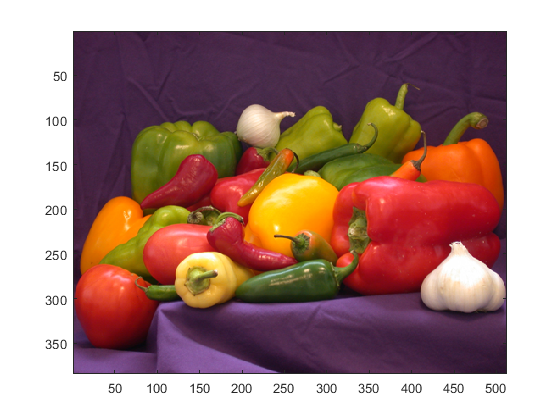

figure;
image(im);

Next, we load a pretrained network. I have picked ResNet-18, which [according to MathWorks](https://www.mathworks.com/help/deeplearning/ref/resnet18.html):

"ResNet-18 is a convolutional neural network that is 18 layers deep. You can load a pretrained version of the network trained on more than a million images from the ImageNet database [[1]](https://www.mathworks.com/help/deeplearning/ref/resnet18.html#mw_591a2746-7267-4890-8390-87ae4dc7204c_sep_mw_6dc28e13-2f10-44a4-9632-9b8d43b376fe). The pretrained network can classify images into 1000 object categories, such as keyboard, mouse, pencil, and many animals. As a result, the network has learned rich feature representations for a wide range of images. The network has an image input size of 224-by-224."

There are many more [pretrained Deep Neural Networks](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html) that you can easily use in MATLAB.

nn = resnet18;

Let's investigate this neural network a bit further.

nn.Layers

ans =   71x1 Layer array with layers:

     1   'data'                              Image Input              224x224x3 images with 'zscore' normalization
     2   'conv1'                             Convolution              64 7x7x3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'                          Batch Normalization      Batch normalization with 64 channels
     4   'conv1_relu'                        ReLU                     ReLU
     5   'pool1'                             Max Pooling              3x3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'                    Convolution              64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     7   'bn2a_branch2a'                     Batch Normalization      Batch normalization with 64 channels
     8   'res2a_branch2a_relu'               ReLU                     ReLU
  

There is a description for each layer in the neural network!

What is the input?

nn.Layers(1).InputSize

ans =    224   224     3


...and output?

nn.Layers(end).Classes

ans = 1000×1 categorical array
     tench 
     goldfish 
     great white shark 
     tiger shark 
     hammerhead 
     electric ray 
     stingray 
     cock 
     hen 
     ostrich 
     brambling 
     goldfinch 
     house finch 
     junco 
     indigo bunting 
     robin 
     bulbul 
     jay 
     magpie 
     chickadee 
     water ouzel 
     kite 
     bald eagle 
     vulture 
     great grey owl 
     European fire salamander 
     common newt 
     eft 
     spotted salamander 
     axolotl 


We see that the input is a 224x224 image, and there are 1000 different output classes that it can classify.

If we want to see the neural network in more detail, we can run

deepNetworkDesigner

Or run it from the "apps" ribbon. 

We will skip this step for now.

To be able to run the network on this image, we must resize it to match the network input shape:

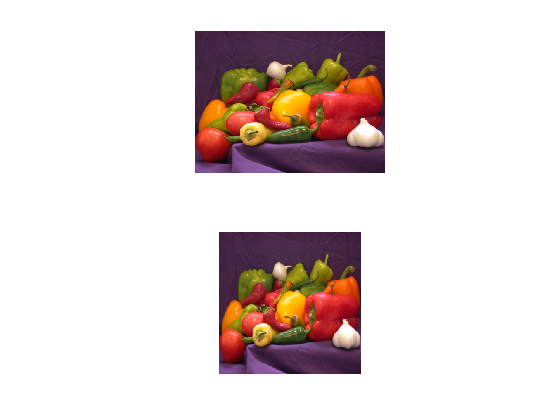

figure;
tiledlayout(2,1);
nexttile;
imshow(im);
nexttile;
im_small = imresize(im, nn.Layers(1).InputSize(1:2));
imshow(im_small);

One can of course change the image in other ways, e.g., crop it.

Next, we classify the image using the neural network:

[label, scores] = classify(nn, im_small);

The network classified the image as

label

label = categorical
     bell pepper 


The top 5 classes that the neural network thought it was are

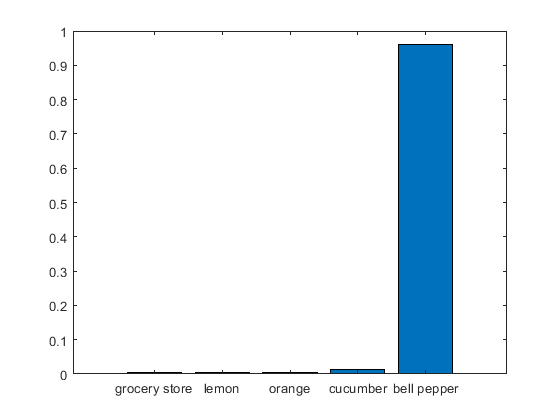

figure;
[~,idx] = sort(scores,'descend');
idx = idx(5:-1:1);
bar(scores(idx))
xticklabels(nn.Layers(end).Classes(idx))

Seems like a reasonable guess!

Here is an image I took yesterday. Let's see if it can classify this

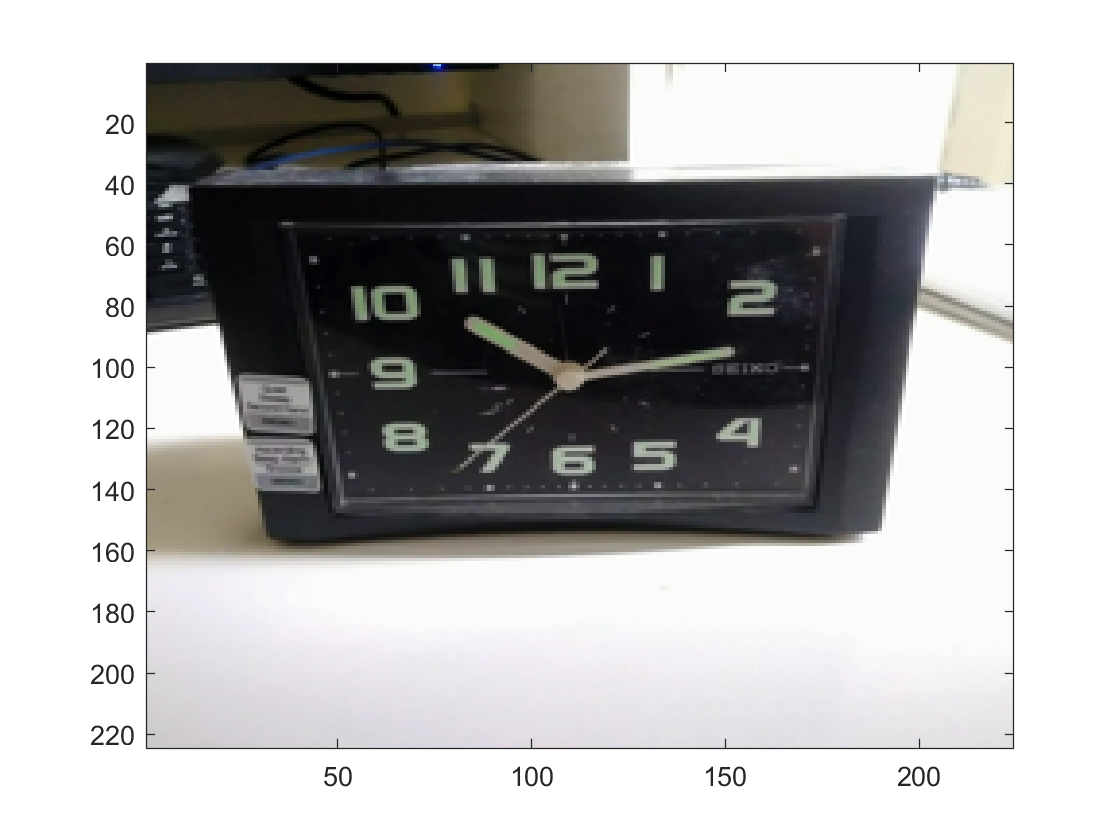

cim = imread("clock.jpg");
cim = imresize(cim, nn.Layers(1).InputSize(1:2));
figure;
image(cim)

classify(nn, cim)

ans = categorical
     analog clock 
